# Assignment 3 - Question 7 - Reza Mansouri - 002784647

## Step 1: Read Stereo Image Pair

I1 = imread("input/question_7/left.jpg");
I2 = imread("input/question_7/right.jpg");

% Convert to grayscale.
I1gray = im2gray(I1);
I2gray = im2gray(I2);

Display both images side by side. Then, display a color composite demonstrating the pixel-wise differences between the images.

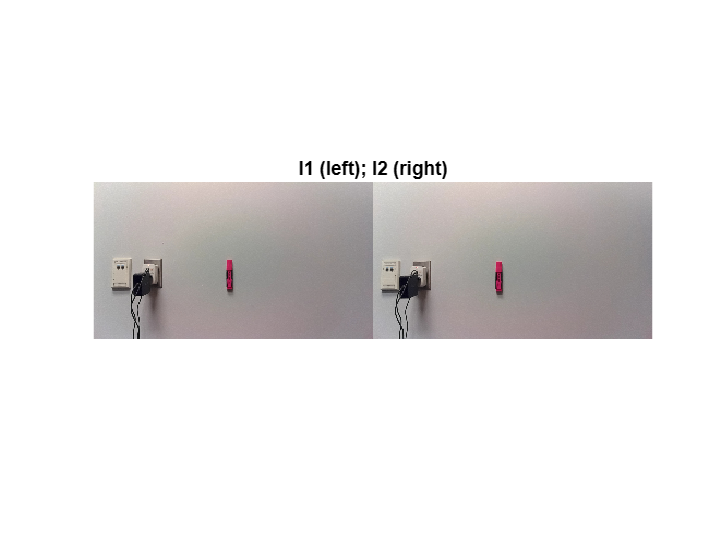

figure
imshowpair(I1,I2,"montage")
title("I1 (left); I2 (right)")

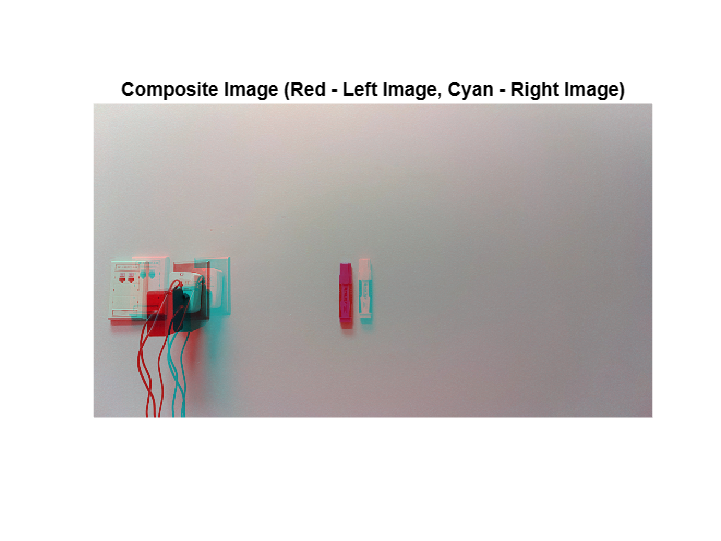

figure 
imshow(stereoAnaglyph(I1,I2))
title("Composite Image (Red - Left Image, Cyan - Right Image)")

## Step 2: Collect Interest Points from Each Image

blobs1 = detectSURFFeatures(I1gray,MetricThreshold=2000);
blobs2 = detectSURFFeatures(I2gray,MetricThreshold=2000);

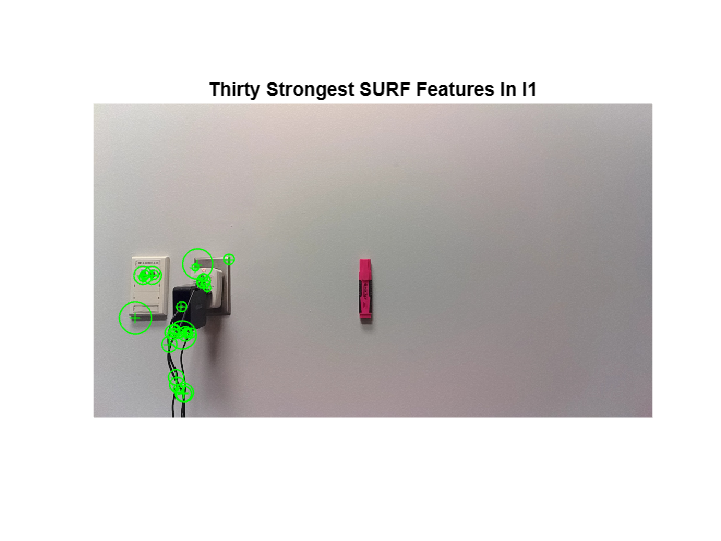

figure 
imshow(I1)
hold on
plot(selectStrongest(blobs1,30))
title("Thirty Strongest SURF Features In I1")

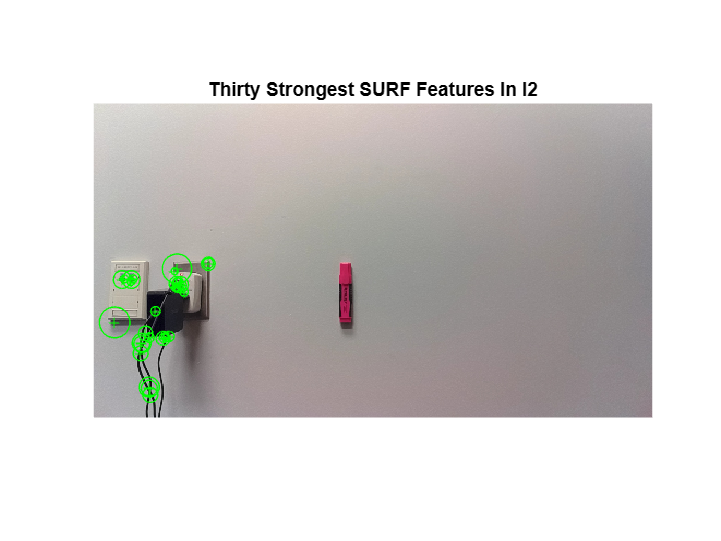

figure
imshow(I2)
hold on
plot(selectStrongest(blobs2,30))
title("Thirty Strongest SURF Features In I2")

## Step 3: Find Putative Point Correspondences

[features1,validBlobs1] = extractFeatures(I1gray,blobs1);
[features2,validBlobs2] = extractFeatures(I2gray,blobs2);

indexPairs = matchFeatures(features1,features2,Metric="SAD", ...
  MatchThreshold=5);

matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);

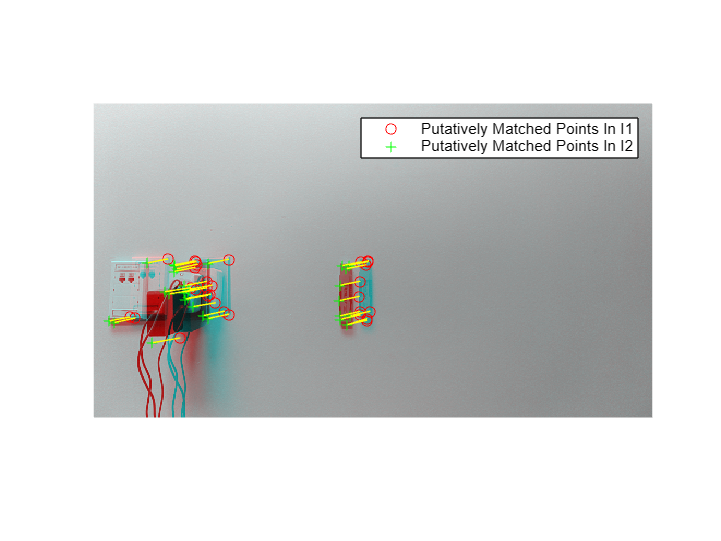

figure 
showMatchedFeatures(I1, I2, matchedPoints1, matchedPoints2)
legend("Putatively Matched Points In I1","Putatively Matched Points In I2")

## Step 4: Remove Outliers Using Epipolar Constraint

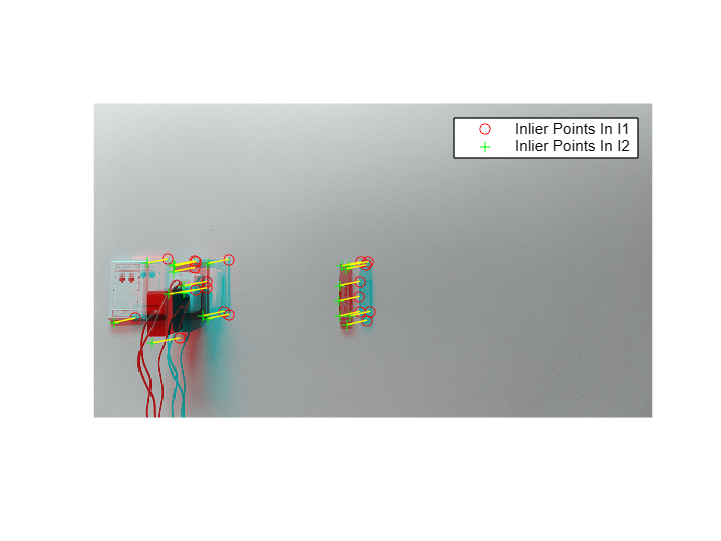

[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1,matchedPoints2,Method="RANSAC", ...
  NumTrials=10000,DistanceThreshold=0.1,Confidence=99.99);
  
if status ~= 0 || isEpipoleInImage(fMatrix,size(I1)) ...
  || isEpipoleInImage(fMatrix',size(I2))
  error(["Not enough matching points were found or "...
         "the epipoles are inside the images. Inspect "...
         "and improve the quality of detected features ",...
         "and images."]);
end

inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);

figure
showMatchedFeatures(I1, I2, inlierPoints1, inlierPoints2)
legend("Inlier Points In I1","Inlier Points In I2")

## Step 5: Rectify Images

[tform1, tform2] = estimateStereoRectification(fMatrix, ...
  inlierPoints1.Location,inlierPoints2.Location,size(I2));

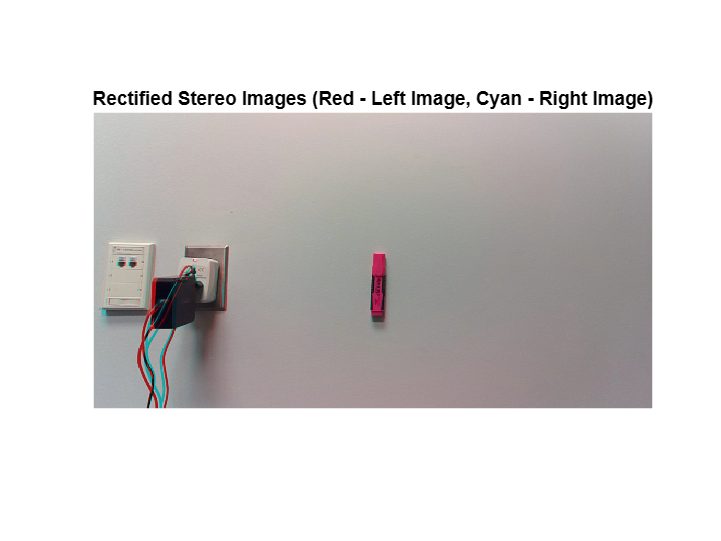

[I1Rect, I2Rect] = rectifyStereoImages(I1,I2,tform1,tform2);
figure
imshow(stereoAnaglyph(I1Rect,I2Rect))
title("Rectified Stereo Images (Red - Left Image, Cyan - Right Image)")

## Step 6: Generalize The Rectification Process

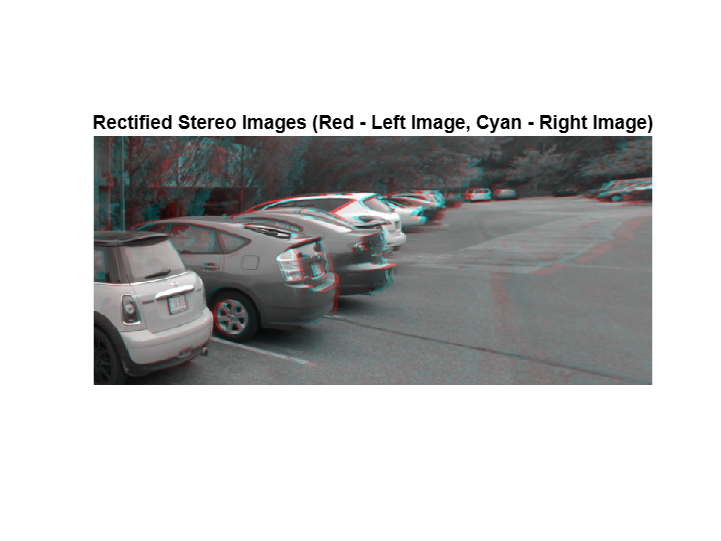

cvexRectifyImages("parkinglot_left.png","parkinglot_right.png");